clc, clear, close all

%--- Information ---

syms p q1(p) q2(p) 
syms a b c

priceDemand=[ 140, 190, 220, 260, 280, 310, 330, 400, 450; 
              1200, 970, 845, 650, 550, 480, 380, 80, 0 ]

priceDemand =          140         190         220         260         280         310         330         400         450
        1200         970         845         650         550         480         380          80           0



tableSize= size(priceDemand,2);
range=max(priceDemand(1,1:tableSize));

%--- Part A - Liner Eq ---

eq1 = a*tableSize+b*sum(priceDemand(1,1:tableSize)) == sum(priceDemand(2,1:tableSize)) ;
eq2 = a*sum(priceDemand(1,1:tableSize)) + b*sum(priceDemand(1,1:tableSize).^2) == sum(priceDemand(2,1:tableSize).*priceDemand(1,1:tableSize));
[A,B] = solve([eq1,eq2],[a,b]);
A=vpa(A,12);
B=vpa(B,12);

q1(p)= A+B*p

$$q1(p) = 1713.4415954415954415901435226033-3.9790598290598290598472225321203\,p$$

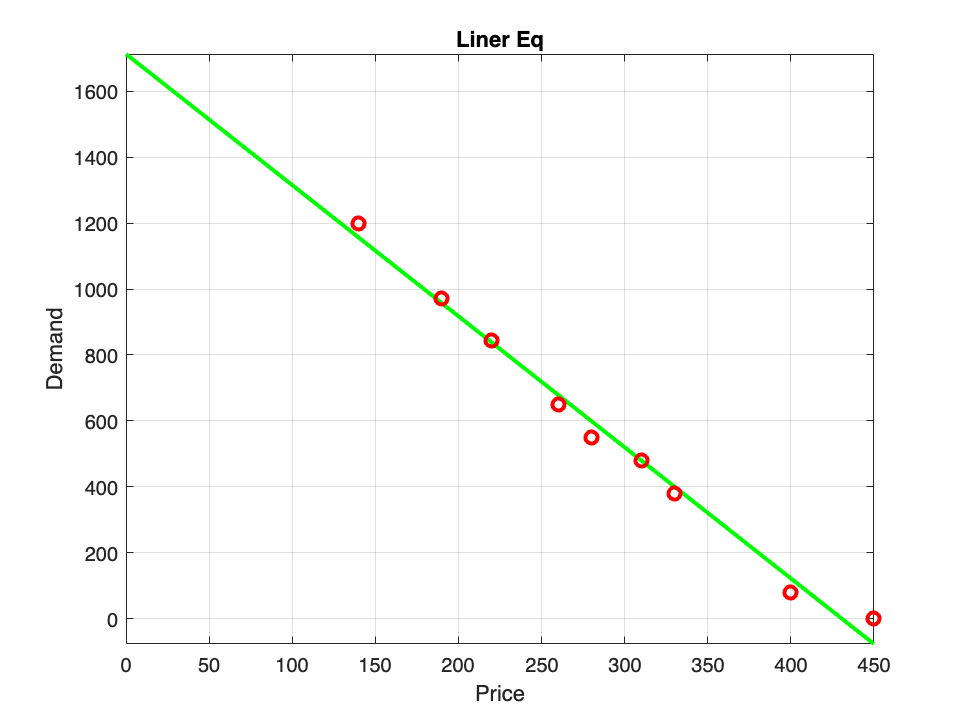


f1=figure;
fplot(q1(p),[0,range],'g','LineWidth',2);
hold on
plot(priceDemand(1,1:tableSize),priceDemand(2,1:tableSize),'o','color','red','LineWidth',2)
title('Liner Eq')
xlabel('Price')
ylabel('Demand')
grid on


error1 = vpa(sum((priceDemand(2,1:tableSize)-q1(priceDemand(1,1:tableSize))).^2),12)

$$error1 = 13488.019943$$


%--- Part B - Quadratic Eq ---

eq1 = a*tableSize+b*sum(priceDemand(1,1:tableSize))+ c*sum(priceDemand(1,1:tableSize).^2) == sum(priceDemand(2,1:tableSize)) ;
eq2 = a*sum(priceDemand(1,1:tableSize)) + b*sum(priceDemand(1,1:tableSize).^2)+ c*sum(priceDemand(1,1:tableSize).^3) == sum(priceDemand(2,1:tableSize).*priceDemand(1,1:tableSize));
eq3 = a*sum(priceDemand(1,1:tableSize).^2) + b*sum(priceDemand(1,1:tableSize).^3)+ c*sum(priceDemand(1,1:tableSize).^4) == sum(priceDemand(2,1:tableSize).*(priceDemand(1,1:tableSize).^2)); 
[A,B,C] = solve([eq1,eq2,eq3],[a,b,c]);
A=vpa(A,12);
B=vpa(B,12);
C=vpa(C,12);

q2(p)=A+B*p+C*(p^2)

$$q2(p) = 0.0034198591258961874130335220200051\,p^{2}-6.0070070611510895958878863964969\,p+1984.1112662707875920475864006676$$

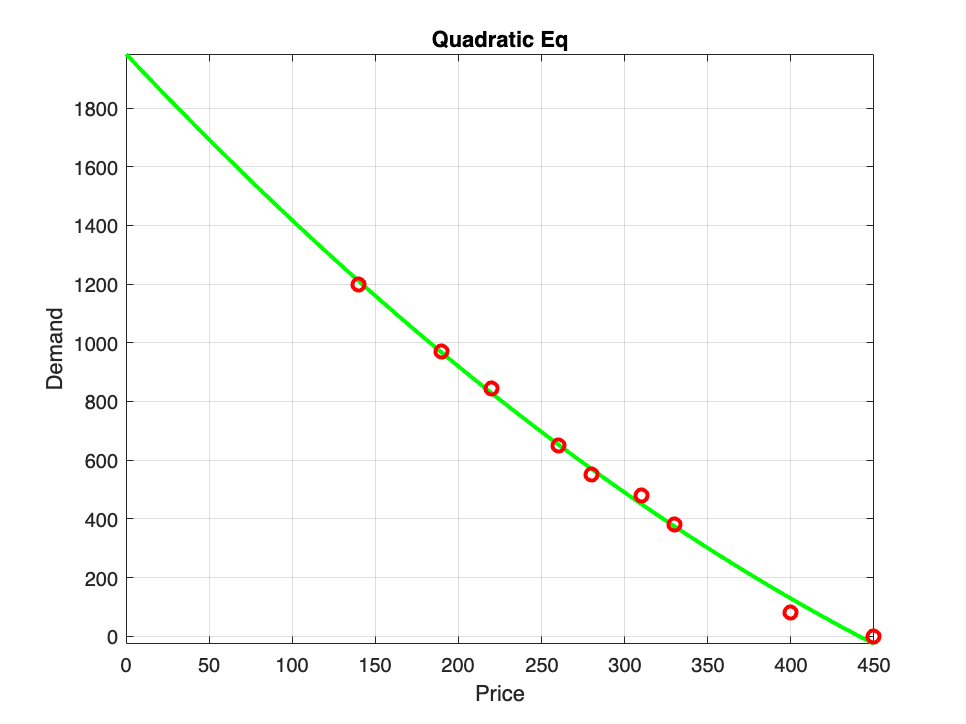


f2=figure;
fplot(q2(p),[0,range],'g','LineWidth',2);
hold on
plot(priceDemand(1,1:tableSize),priceDemand(2,1:tableSize),'o','color','red','LineWidth',2)
title('Quadratic Eq')
xlabel('Price')
ylabel('Demand')
grid on


error2 = vpa(sum((priceDemand(2,1:tableSize)-q2(priceDemand(1,1:tableSize))).^2),12)

$$error2 = 4778.76895922$$


%--- Part C - Question ---

maxErorr=0.5;

totalError1= abs(priceDemand(2,1:tableSize)-q1(priceDemand(1,1:tableSize)));
totalError2= abs(priceDemand(2,1:tableSize)-q2(priceDemand(1,1:tableSize)));

indeces1= find(maxErorr > totalError1);
indeces2= find(maxErorr > totalError2);

price1= priceDemand(1,indeces1)

price1 = 310

price2= priceDemand(1,indeces2) 


price2 =

  1×0 empty double row vector

